Здесь используется RigidBodyTree библиотека матлаб, а также стандарт описания роботов во фреймворке ROS/ROS2. Тем самым мы конвертируем структуру нашего робота из ROS фреймворка в среду RibidBodyTree матлаба. Что даёт доступ ко многим стандартным алгоритмам и просто удобнее

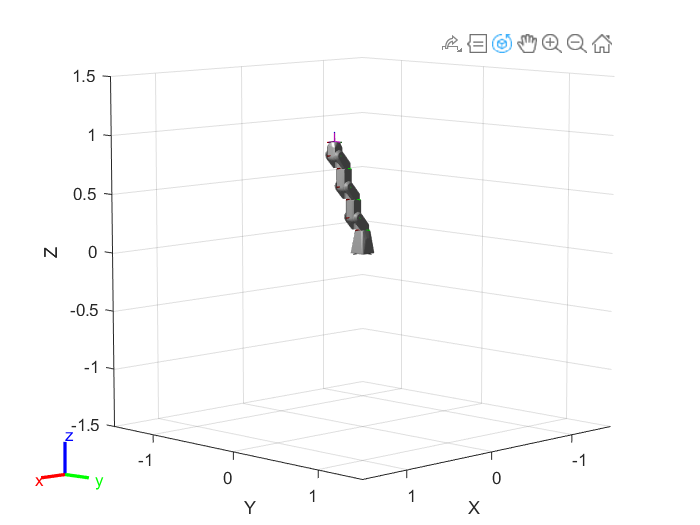

% импорт робота из файла (стандарт ROS для описания моделей)
robot = importrobot("robot_arm\urdf\robossembler_arm.urdf");
% Показываем робота на трёхмерном графике, если Visuals off, тогда меши не
% отображатся
show(robot,"Visuals","on");

% Не помню для чего, можешь сам узнать, но не мешает :)
robot.DataFormat = "column";
% Устанавливаем вектор гравитационных сил
robot.Gravity = [0,0,-9.81];

% Maximum number of waypoints (for Simulink)
maxWaypoints = 20;
% Получаем вектор обобщённых координат для начального положения робота (Home Position в простонароде)
q0 = robot.homeConfiguration;
% Получаем точку эффектора XYZ часть
start_vec = tform2trvec(getTransform(robot,q0,"tool0"))

start_vec =     0.3310         0    0.9734


% Задаём координаты эффектора для каждой точки
traectory =[0.5 0.5 0.1;
            0.5 0.33 0.17 ; 
            0.5 0.16 0.34 ; 
            0.5 0 0.6 ; 
            0.5 -0.16 0.34 ; 
            0.5 -0.33 0.17;
            0.5 -0.5 0.1;
            0.5 0.5 0.1]

traectory =     0.5000    0.5000    0.1000
    0.5000    0.3300    0.1700
    0.5000    0.1600    0.3400
    0.5000         0    0.6000
    0.5000   -0.1600    0.3400
    0.5000   -0.3300    0.1700
    0.5000   -0.5000    0.1000
    0.5000    0.5000    0.1000


% Это просто транспонирование
waypoints = traectory'

waypoints =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.3300    0.1600         0   -0.1600   -0.3300   -0.5000    0.5000
    0.1000    0.1700    0.3400    0.6000    0.3400    0.1700    0.1000    0.1000


% Углы Эйлера для каждой точки (Z Y X)       
orientations = [0     pi     0;
                0     pi/2  0; 
                0     pi/3  0;
                0     pi/4  pi/3;
                0     pi/5  0;
                0     pi/6  0;
                0     pi  0;
                0     pi    0]';   
            
% Array of waypoint times
t_vel = 2

t_vel = 2

waypointTimes = 0:t_vel:t_vel*7

waypointTimes =      0     2     4     6     8    10    12    14



% Trajectory sample time
ts = 0.01;
trajTimes = 0:ts:waypointTimes(end);

%% Additional parameters

% Boundary conditions (for polynomial trajectories)
% Velocity (cubic and quintic)
waypointVels = 0.1 *[-1  0  0;
                      0 -1  0;
                      1  0  0;
                      0  1  0;
                      0  1  0;
                      0  1  0;
                      0  1  0;
                      0  1  0]';

% Acceleration (quintic only)
waypointAccels = zeros(size(waypointVels));

% Acceleration times (trapezoidal only)
waypointAccelTimes = diff(waypointTimes)/4;
